# **Onda Quadrada**

Para criar um sinal de teste quadrado, primeiramente é necessário determinar a frequência da onda. Por exemplo, desejamos gerar um sinal senoidal com f = 10 Hz e com amplitude mínima e máxima de -1 V e 1 V, respectivamente

f = 10; % Hz, frequência da onda quadrada
V = 1; % V, amplitude da onda quadrada

Após determinados a frequência e amplitude, o próximo passo é determinar a taxa de amostragem. Respeitando o Teorema de amostragem de Nyquist-Shannon, para reproduzir o sinal fielmente no domínio da frequência é necessário que a taxa de amostragem *fs *seja igual ou maior que pelo menos duas vezes a frequência máxima *fm *$\left(fs\ge 2\cdot fm\right)\ldotp \;$A taxa de sobreamostragem é utilizada aumentar a taxa de amostragem além do mínimo exigido pelo teorema de Nyquist-Shannon. 

overSampRate = 30; % taxa de sobreamostragem 
fs = overSampRate*f; % taxa de amostragem

O próximo passo é determinar o número de ciclos desejados para o sinal e a base de tempo para representação do tempo ao longo dos ciclos completos da onda quadrada. 

nCyl = 5; % gera cinco ciclos da onda
t = 0:1/fs:nCyl*1/f-1/fs; % base de tempo

Agora basta representar o sinal. As ondas quadradas verdadeiras são uma classe especial de ondas retangulares com ciclo de trabalho de 50%. A função sinal (signum) retorna -1 para valores negativos, 0 para zero e +1 para valores positivos. Quando aplicada a uma função periódica, como uma senoide, por exemplo, ela transforma a função em uma forma de onda quadrada, alternando entre -1 e +1 nos pontos onde a função original cruza o eixo horizontal (zero). Isso cria uma onda quadrada com um ciclo de trabalho de 50%, o que significa que a metade do período é passada acima do eixo zero e a outra metade abaixo dele.

g = V*sign(sin(2*pi*f*t)); % equação do sinal

Plotando o sinal.

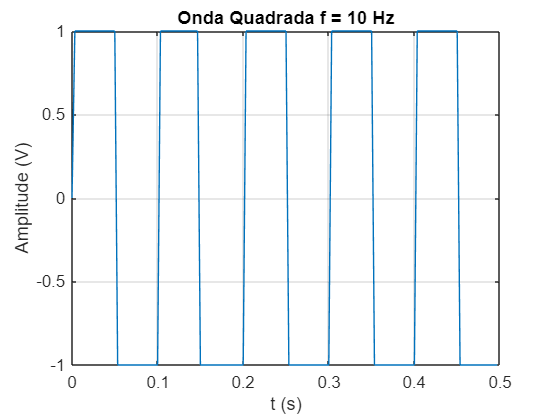

plot(t,g); % plota o sinal
grid on; % mostra linhas de grade
title(['Onda Quadrada f = ', num2str(f), ' Hz']); % adiciona título
xlabel('t (s)'); % adiciona título no eixo x
ylabel('Amplitude (V)'); % adiciona título no eixo y